# 分類用のシンプルな深層学習ネットワークの作成

この例では、深層学習による分類用のシンプルな畳み込みニューラル ネットワークを作成し、学習を行う方法を説明します。畳み込みニューラル ネットワークは深層学習に不可欠なツールであり、特にイメージの認識に適しています。

この例では、以下を実行する方法を示します。

- イメージ データの読み込みと確認

- ネットワーク アーキテクチャの定義

- 学習オプションの指定

- ネットワークに学習をさせます

- 新しいデータのラベルの予測と分類精度の計算

## **イメージ データの読み込みと確認**

数字の標本データをイメージ データストアとして読み込みます。`imageDatastore` は、フォルダー名に基づいてイメージに自動的にラベルを付け、データを `ImageDatastore` オブジェクトとして格納します。イメージ データストアを使用すると、メモリに収まらないデータなどの大きなイメージ データを格納し、畳み込みニューラル ネットワークの学習中にイメージをバッチ単位で効率的に読み取ることができます。

digitDatasetPath = fullfile(matlabroot,'toolbox','nnet','nndemos', ...
    'nndatasets','DigitDataset');
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true,'LabelSource','foldernames');

データストアのイメージをいくつか表示します。

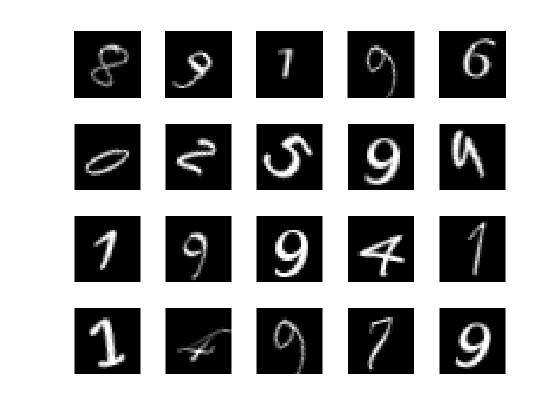

figure;
perm = randperm(10000,20);
for i = 1:20
    subplot(4,5,i);
    imshow(imds.Files{perm(i)});
end

各カテゴリのイメージの数を計算します。`labelCount` は、ラベル、およびそれぞれのラベルが付いているイメージの数を格納する table です。データストアには 0 ～ 9 の数字それぞれについて 1000 個のイメージ、合計で 10000 個のイメージが含まれます。ネットワークの最後の全結合層のクラス数を引数 `OutputSize` として指定できます。

labelCount = countEachLabel(imds)

labelCount = 10×2 table
    Label    Count
    _____    _____

      0      1000 
      1      1000 
      2      1000 
      3      1000 
      4      1000 
      5      1000 
      6      1000 
      7      1000 
      8      1000 
      9      1000 


ネットワークの入力層にイメージのサイズを指定しなければなりません。`digitData` の最初のイメージのサイズを確認します。イメージはそれぞれ 28 x 28 x 1 ピクセルです。

img = readimage(imds,1);
size(img)

ans =     28    28


## **学習セットと検証セットの指定**

データを学習データセットと検証データセットに分割し、学習セットの各カテゴリに 750 個のイメージが含まれ、検証セットに各ラベルの残りのイメージが含まれるようにします。`splitEachLabel` は、データストア `digitData` を 2 つの新しいデータストア `trainDigitData` と `valDigitData` に分割します。

numTrainFiles = 750;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## **ネットワーク アーキテクチャの定義**

畳み込みニューラル ネットワーク アーキテクチャを定義します。

layers = [
    imageInputLayer([28 28 1])
    
    convolution2dLayer(3,8,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,16,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    maxPooling2dLayer(2,'Stride',2)
    
    convolution2dLayer(3,32,'Padding','same')
    batchNormalizationLayer
    reluLayer
    
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer];

**イメージ入力層**

 [`imageInputLayer`](https://jp.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.imageinputlayer.html) にはイメージ サイズを指定します。ここでは 28 x 28 x 1 です。これらの数値は、高さ、幅、およびチャネル サイズに対応します。数字データはグレースケール イメージで構成されるため、チャネル サイズ (カラー チャネル) は 1 です。カラー イメージの場合、RGB 値に対応してチャネル サイズは 3 になります。データは、`trainNetwork` により既定で学習の開始時にシャッフルされるため、シャッフルの必要はありません。学習時の各エポックの開始時にも、`trainNetwork` によりデータは自動的にシャッフルされます。

**畳み込み層**

 畳み込み層の最初の引数は `filterSize` です。これは、イメージのスキャン時に学習関数によって使用されるフィルターの高さと幅を示します。この例では、3 という数字によってフィルター サイズが 3 x 3 であることを示しています。フィルターの高さと幅には異なるサイズを指定できます。2 つ目の引数 `numFilters` はフィルターの数です。これは、入力の同じ領域に結合するニューロンの数を示します。このパラメーターによって、特徴マップの数が決定されます。名前と値のペア `'Padding'` を使用して、入力の特徴マップにパディングを追加します。既定のストライドが 1 の畳み込み層の場合、`'same'` パディングによって空間の出力サイズが入力サイズと同じになります。[`convolution2dLayer`](https://jp.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.convolution2dlayer.html) の名前と値のペアの引数を使用して、この層のストライドと学習率を定義することもできます。

**バッチ正規化層**

 バッチ正規化層は、ニューラル ネットワークを通じて伝播される活性化と勾配を正規化します。これにより、ネットワークの学習は簡単な最適化問題になります。畳み込み層の間にあるバッチ正規化層と、ReLU 層などの非線形性を使用して、ネットワークの学習速度を上げ、ネットワークの初期化に対する感度を下げます。[`batchNormalizationLayer`](https://jp.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.batchnormalizationlayer.html) を使用して、バッチ正規化層を作成します。

**ReLU 層**

バッチ正規化層の後に非線形活性化関数が続きます。最も一般的な活性化関数は、正規化線形ユニット (ReLU) です。[`reluLayer`](https://jp.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.relulayer.html) を使用して、ReLU 層を作成します。

**最大プーリング層**

 畳み込み層 (と活性化関数) の後で、ダウンサンプリング処理を行うことがあります。これにより、特徴マップの空間サイズが縮小され、冗長な空間情報が削除されます。ダウンサンプリングでは、層ごとに必要な計算量を増やさずに、より深い畳み込み層のフィルターの数を増やすことができます。ダウンサンプリングの 1 つの方法が最大プーリングの使用です。これは、[`maxPooling2dLayer`](https://jp.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.maxpooling2dlayer.html) を使用して作成します。最大プーリング層は、最初の引数 `poolSize` によって指定された、入力の矩形領域の最大値を返します。この例では、矩形領域のサイズは [2,2] です。名前と値のペアの引数 `'Stride'` は、入力に沿ってスキャンするときに学習関数が取るステップ サイズを指定します。

**全結合層**

 畳み込み層とダウンサンプリング層の後には、1 つ以上の全結合層を配置します。その名前からわかるように、全結合層はニューロンが前の層のすべてのニューロンに結合している層です。この層は、前の層によってイメージ全体で学習されたすべての特徴を組み合わせて、より大きなパターンを特定します。最後の全結合層は、これらの特徴を組み合わせてイメージを分類します。そのため、最後の全結合層の `OutputSize` パラメーターは、ターゲット データのクラスの数と等しくなります。この例では、10 個のクラスに対応して、出力サイズが 10 になっています。[`fullyConnectedLayer`](https://jp.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.fullyconnectedlayer.html) を使用して、全結合層を作成します。

**ソフトマックス層**

 ソフトマックス活性化関数は、全結合層の出力を正規化します。ソフトマックス層の出力は合計が 1 になる正の数値で構成されており、分類層で分類の確率として使用できます。最後の全結合層の後に関数 [`softmaxLayer`](https://jp.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.softmaxlayer.html) を使用してソフトマックス層を作成します。

**分類層**

 最後の層は分類層です。この層は、ソフトマックス活性化関数によって各入力について返された確率を使用して、互いに排他的なクラスの 1 つに入力を割り当て、損失を計算します。分類層を作成するには、[`classificationLayer`](https://jp.mathworks.com/help/deeplearning/ref/classificationlayer.html) を使用します。

## **学習オプションの指定**

ネットワーク構造を定義した後、学習オプションを指定します。初期学習率を 0.01 としたモーメンタム項付き確率的勾配降下法 (SGDM) を使用して、ネットワークに学習させます。エポックの最大数を 4 に設定します。エポックとは、学習データセット全体の完全な学習サイクルのことです。検証データと検証頻度を指定して、学習中にネットワークの精度を監視します。すべてのエポックでデータをシャッフルします。学習データでネットワークに学習させ、学習中に一定の間隔で検証データに対してその精度を計算します。検証データは、ネットワークの重みの更新には使用されません。学習の進行状況プロットをオンにして、コマンド ウィンドウの出力をオフにします。

options = trainingOptions('sgdm', ...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

## **学習データを使用したネットワークの学習**

`layers`、学習データ、および学習オプションによって定義されたアーキテクチャを使用して、ネットワークに学習させます。既定では、利用可能な GPU がある場合、`trainNetwork` は GPU を使用します (Parallel Computing Toolbox™、および Compute Capability 3.0 以上の CUDA® 対応 GPU が必要)。そうでない場合は CPU が使用されます。`trainingOptions` の名前と値のペアの引数 `'ExecutionEnvironment'` を使用して、実行環境を指定することもできます。

学習の進行状況プロットには、ミニバッチの損失と精度、および検証の損失と精度が表示されます。学習の進行状況プロットの詳細は、[深層学習における学習の進行状況の監視](https://jp.mathworks.com/help/deeplearning/ug/monitor-deep-learning-training-progress.html)を参照してください。損失は交差エントロピー損失です。精度は、ネットワークによって正しく分類されるイメージの割合です。

net = trainNetwork(imdsTrain,layers,options);

## **検証イメージの分類と精度の計算**

学習済みネットワークを使用して検証データのラベルを予測し、最終検証精度を計算します。精度とは、ネットワークによって予測が正しく行われるラベルの割合です。この場合、99% を超える予測ラベルが検証セット内の真のラベルに一致しています。

YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;

accuracy = sum(YPred == YValidation)/numel(YValidation)

accuracy = 0.9872

*Copyright 2012-2021 The MathWorks, Inc. *